- `采用相同光谱，不考虑样品色散，仅考虑系统色散（系统色散厚度变化）对白光干涉信号参数、测量结果的影响。改变系统色散厚度变化，观察白光干涉信号变化。分别采用多种方法验证系统色散对白光干涉测量的影响。`对于两光路对称或色散忽略的情形下，干涉条纹强度最大的位置是零光程差对应的零级干涉条纹，零级干涉条纹处的可见度最大。当存在色散时，干涉条纹可见度最大的位置与光强度最大的位置并不重合；若以最大光强度位置作为零光程差会出现四分之一中心波长的系统误差。

- 系统色散对白光干涉测量的影响：（1）对白光干涉信号的影响：白光干涉信号不再关于零相位点所在位置对称，其包络变成不规则形状。（2）对白光干涉测量的影响：当存在色散时，干涉条纹可见度最大的位置与光强度最大的位置并不重合；若以最大光强度位置作为零光程差会出现四分之一中心波长的系统误差。

- 对于相同的物体表面位置，当T(厚度差)= 20um时，采用直接求解最大值、插值高斯包络拟合法、重心法、插值法、频域法和波数域相位补偿法求得的物体表面形貌位置分别为19.3700、19.3216、

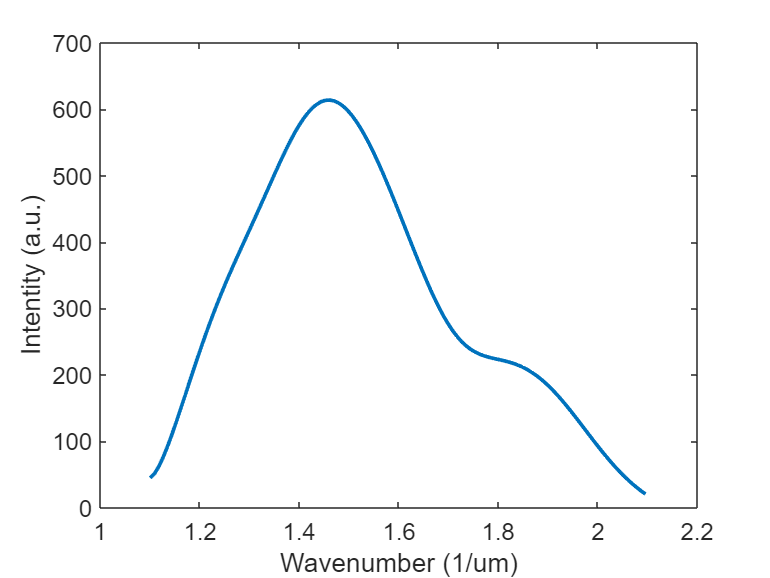

clc; clear all;
%显示光谱信息
format long
spectrum = readtable("Isigma.xls","ReadVariableNames",false);
spectrum_frequency = (spectrum{:,1})';
spectrum_intensity = (spectrum{:,2})';
%disp("全部光谱信息");
% plot(spectrum_frequency,spectrum_intensity)
%找出探测器对应的光谱，这里假设是1.1-2.1
[~, indix_min] = min(abs(spectrum_frequency-1.1));
[~, indix_max] = min(abs(spectrum_frequency-2.1));
spectrum_frequency = spectrum_frequency(indix_min:indix_max);
spectrum_intensity = spectrum_intensity(indix_min:indix_max);
%disp("需要的光谱信息");
plot(spectrum_frequency,spectrum_intensity,'LineWidth',2);
xlabel('Wavenumber (1/um)') 
ylabel('Intentity (a.u.)')
ax = gca;
ax.FontSize = 13;

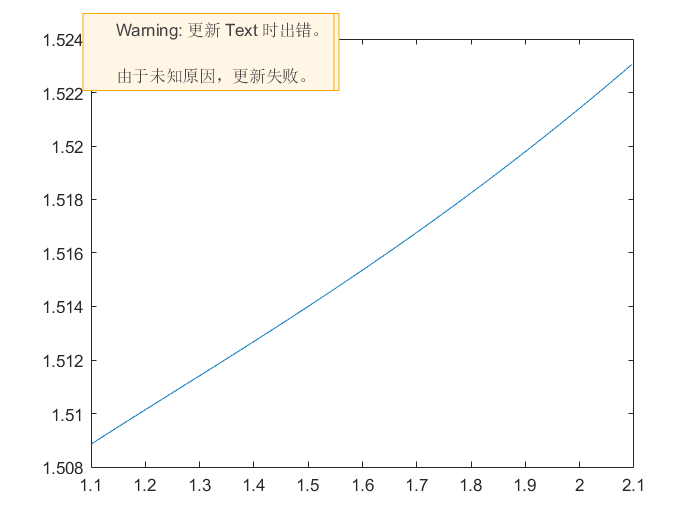


lambda = 1./spectrum_frequency;
index2 = (1.03961212*lambda.^2)./(lambda.^2-0.00600069867)+(1.01046945*lambda.^2)./(lambda.^2-103.560653)+...
        (0.231792344*lambda.^2)./(lambda.^2-0.0200179144)+1; 
index = sqrt(abs(index2));
%折射率曲线
%disp("折射率曲线");
plot(spectrum_frequency,index);

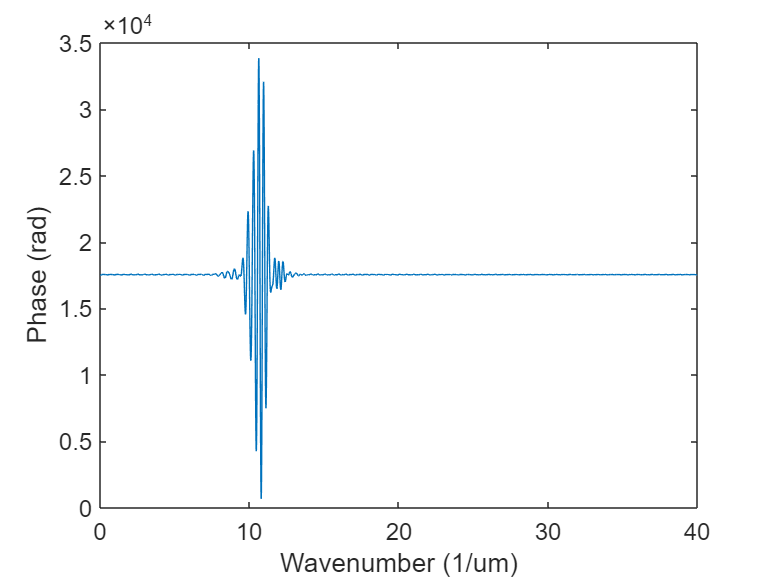

%色散
T = 2000;
lEpsilon = T*0.01; %单位为微米
z0 = 0;    %单位为微米
N = 4000;
z = 0:40/4000:(N-1)*(40/4000);
interference_signal1 = zeros(1,length(z));
for i = 1:length(z)
        interference_signal1(i) = sum(spectrum_intensity./2+...
        spectrum_intensity./2.*cos(4*pi*(z(i)-z0).*spectrum_frequency-...
        4*pi*(index-1).*spectrum_frequency*lEpsilon));
end
%disp("生成有色散的白光干涉信号");
plot(z,interference_signal1);
% plot(spectrum_frequency,Phase,'LineWidth',2);
xlabel('Wavenumber (1/um)') 
ylabel('Phase (rad)')
ax = gca;
ax.FontSize = 13;

直接求解最大值：

[~, loc]=max(interference_signal1);
zhijie = z(loc)

zhijie =   10.630000000000001


采用相干峰寻址法测量：高斯包络拟合法（白光干涉光强曲线符合高斯包络调制，对白光 干涉光强的高斯包络进行拟合，取其极值点的横坐 标就是该点对应的相干峰的坐标）

interference_signal = interference_signal1-mean(interference_signal1);
baoluo = hilbert(interference_signal); % Hilbert变换
baoluo = abs(baoluo);
plot(z,interference_signal);
guass = fit(z.',baoluo.','gauss1')

guass =      General model Gauss1:
     guass(x) =  a1*exp(-((x-b1)/c1)^2)
     Coefficients (with 95% confidence bounds):
       a1 =    1.65e+04  (1.642e+04, 1.658e+04)
       b1 =       10.68  (10.68, 10.68)
       c1 =      0.5974  (0.5941, 0.6008)

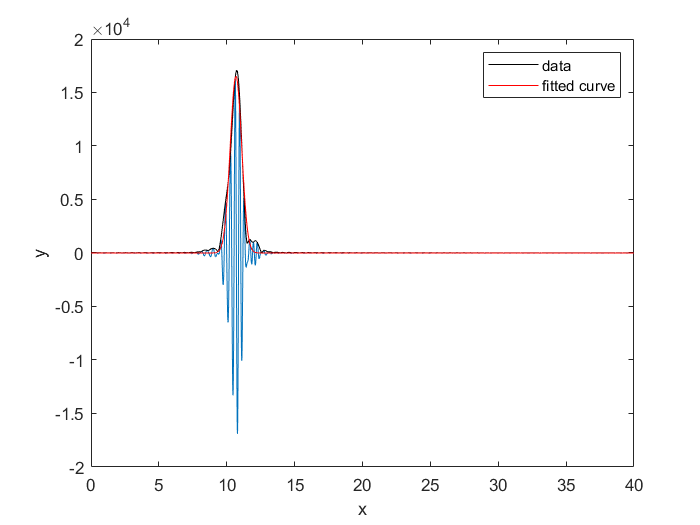

hold on
plot(guass,z,baoluo,'-k')
hold off

baoluoguass = guass.b1

baoluoguass =   10.678424482775291


%重心法：

interference_signal = interference_signal1;
zhongxin = zxf(interference_signal);
zhongxin = round(zhongxin);
zhongxin = z(zhongxin)

zhongxin =   10.700000000000001


插值法

[~,loc1]=max(interference_signal1);


基于相位的测量方法：傅里叶变换法:傅里叶正变换后选择其正频率部分，然后再进行傅里叶逆变换就会得到白光干涉信号的幅度谱和相位谱。从傅里叶变换法来看，有色散的白光干涉信号（复数形式）的幅度谱最大值所在位置和相位谱零点所在位置并不相等。

%对光谱进行傅里叶变换
interference_signal = interference_signal1-mean(interference_signal1);
% plot(z,interference_signal);
%fft补零
Nftt = 2^15;
f_interference_signal = fft(interference_signal,Nftt);
Fs = 1/(40/4000);
deltaSigma = Fs/(2*Nftt);
sigma = (0:Nftt/2)*deltaSigma;
f_interference_signal = ifft(f_interference_signal(1:numel(f_interference_signal)/2),Nftt);
interference_signal = ifftshift(f_interference_signal);
deltaSigma = (sigma(end)-sigma(1))/(length(sigma)-1);
deltaZ = 1/(2*Nftt*deltaSigma);
z = (1:Nftt)*deltaZ;
intensity_fft = abs(interference_signal);
angle_fft = angle(interference_signal);
%坐标变换
z = z-z(end)/2;
intensity = intensity_fft;
zData = z;
phase = angle_fft;
[~,index3]= max(intensity);
za1 = zData(index3);
%-----------------------------------
[~,indexend] = min(abs(zData-(za1+0.5)));
[~,indexstart] = min(abs(zData-(za1-0.5)));
unwrapZend = zData(indexend);
unwrapZ_1 = zData(indexstart);
unwrapN1 = index3;
unwrapNe = find(zData==unwrapZend);
unwrapN_1 = find(zData==unwrapZ_1);
unwrapPha = zeros(1,length(zData));
unwrapPha(unwrapN1) = phase(index3);
for n = unwrapN1+1:unwrapNe
    diff = phase(n)-phase(n-1);
    if diff > pi/2
       unwrapPha(n) = unwrapPha(n-1)+diff-2*pi;
    elseif diff < -pi/2
       unwrapPha(n) = unwrapPha(n-1)+diff+2*pi;
    else
       unwrapPha(n) = unwrapPha(n-1)+diff;
    end
end
for n = unwrapN1:-1:unwrapN_1
    diff = phase(n)-phase(n-1);
    if diff > pi/2
       unwrapPha(n-1) = unwrapPha(n)-diff+2*pi;
    elseif diff < -pi/2
       unwrapPha(n-1) = unwrapPha(n)-diff-2*pi;
    else
       unwrapPha(n-1) = unwrapPha(n)-diff;
    end
end
% plot(zData(unwrapN_1:unwrapNe),unwrapPha(unwrapN_1:unwrapNe));
phase1=unwrapPha(unwrapN_1:unwrapNe);
zData1=zData(unwrapN_1:unwrapNe);
indexP = find(phase1>0);
indexN = find(phase1<0);
[phaseP,indexZP]= min(phase1(indexP));
[phaseN,indexZN]= max(phase1(indexN));
zData0P = zData1(indexP(indexZP));
zData0N = zData1(indexN(indexZN));
if za1<0
zp1 = ((zData0N-zData0P)*phaseN)/(phaseP-phaseN)+zData0N-zData(end)
za1 = za1-zData(end)
zData = zData - zData(end);
else
zp1 = ((zData0N-zData0P)*phaseN)/(phaseP-phaseN)+zData0N
za1
end

zp1 =   10.633772147743532


za1 =   10.750000000000000


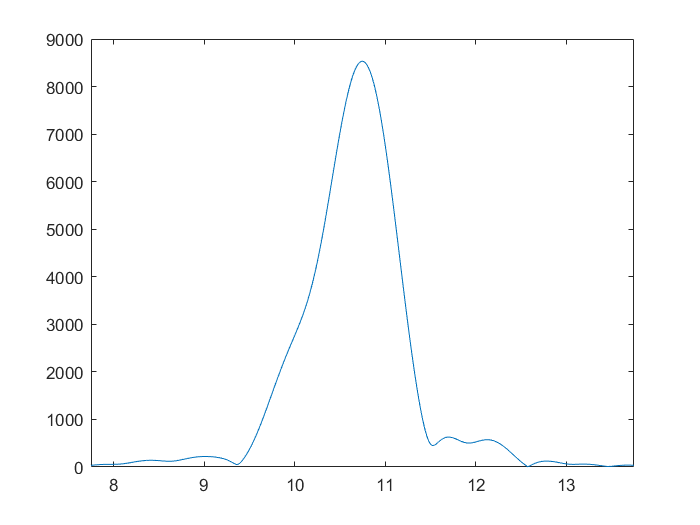

plot(zData,intensity);xlim([zData(index3)-3 zData(index3)+3]);

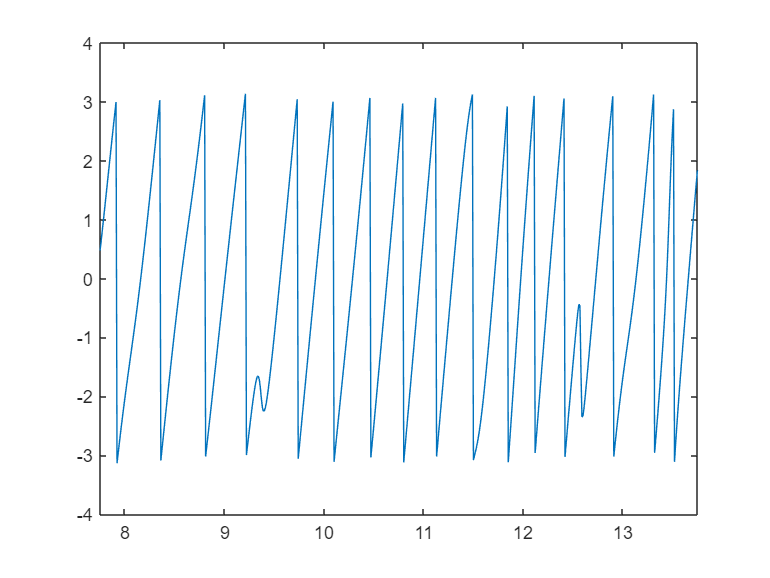

plot(zData,phase);xlim([zData(index3)-3 zData(index3)+3]);

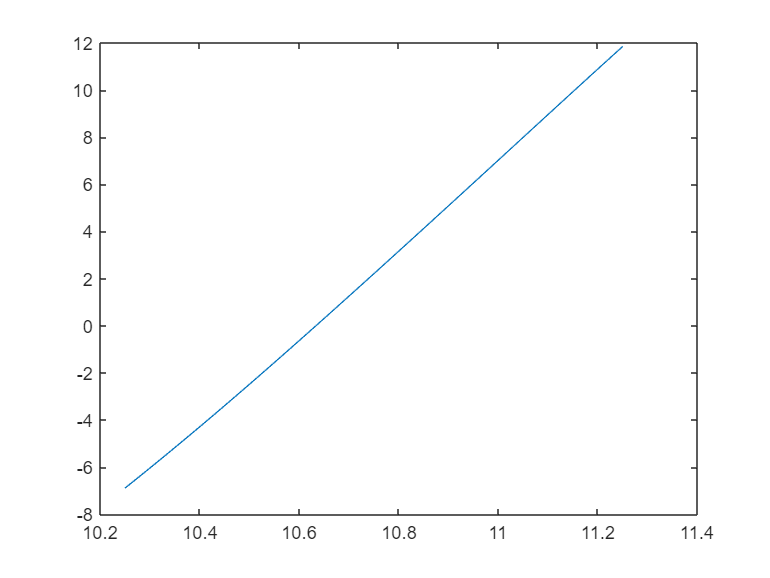

plot(zData(unwrapN_1:unwrapNe),unwrapPha(unwrapN_1:unwrapNe));

function center1 = zxf(I3)
I_V=diff(I3);
I_V1=I_V.^2;
xx=1:length(I_V1);
center1=sum(I_V1.*xx)/sum(abs(I_V1));
end

